# DESCOMPOSICIÓN EN VALORES SINGULARES

# INTERPRETACIÓN GEOMÉTRICA

Como se sabe, dada una matriz $A\in {\cal M}_{m\times n}$ de $m$ filas y $n$ columnas puede escribirse como


$$A=USV^{\rm T}$$


donde $U\in {\cal M}_{m}$ y $V\in {\cal M}_{n}$ son matrices ortogonales (i.e. $U^{\rm T}U=I_m, V^{\rm T}V=I_n$) y $S\in {\cal M}_{m\times n}$ es una matriz diagonal. Una demostración sencilla de esto puede encontrarse en [este artículo](https://es.wikipedia.org/wiki/Descomposici%C3%B3n_en_valores_singulares) de Wikipedia.

Si reescribimos la ecuación anterior como


$$AV=US$$


podemos interpretarla como que existe una base **ortonormal** de $\mathbb{R}^{n}$ (las columnas de $V$) que se transforma por $A$ en una base **ortogonal** de $\mathbb{R}^{m}$(las columnas de $U$, cada una de ellas multiplicada por el elemento correspondiente de la diagonal de $S$).

De esta forma, la esfera unidad del primer espacio se convierte en un elipsoide en el segundo cuyos ejes son, precisamente, el citado sistema ortogonal en $\mathbb{R}^{m}$. Vamos a ver esto en el caso en que $m,n=2$. Recordamos que, en el plano, las matrices ortogonales representan isometrías (una rotación alrededor del origen o una reflexión respecto a una recta que pasa por el origen).

(Moviendo los deslizadores se generan distintas matrices de tamaño $2\times 2$. Los deslizadores se mueven en números enteros, pero escribiendo en las casillas se puede tomar cualquier número entre -10 y 10).

A11=1; A12=1;
A21=1; A22=-2;
A=[A11 A12; A21 A22];

t=0:2*pi/100:2*pi;
x=cos(t);
y=sin(t);
p=[x;y];
[U,S,V]=svd(A);

Dada la matriz


$$A=$$


disp(A)

     1     1
     1    -2



su descomposición en valores singulares$A=USV^{\rm T}$ es


$$U=$$


disp(U)

   -0.2898    0.9571
    0.9571    0.2898




$$S=$$


disp(S)

    2.3028         0
         0    1.3028




$$V=$$


disp(V)

    0.2898    0.9571
   -0.9571    0.2898



En la siguiente figura se muestra cómo varía la circunferencia unidad según se van multiplicando sus puntos por $V^{\rm T}, S$ y $U$. Los ejes que se dibujan son, respectivamente, las columnas de $V$, sus transformados por $V^{\rm T}$ (es decir, la base canónica), la dilatación de esta como resultado de multiplicar por $S$ y, finalmente, la rotación correspondiente a $U$.

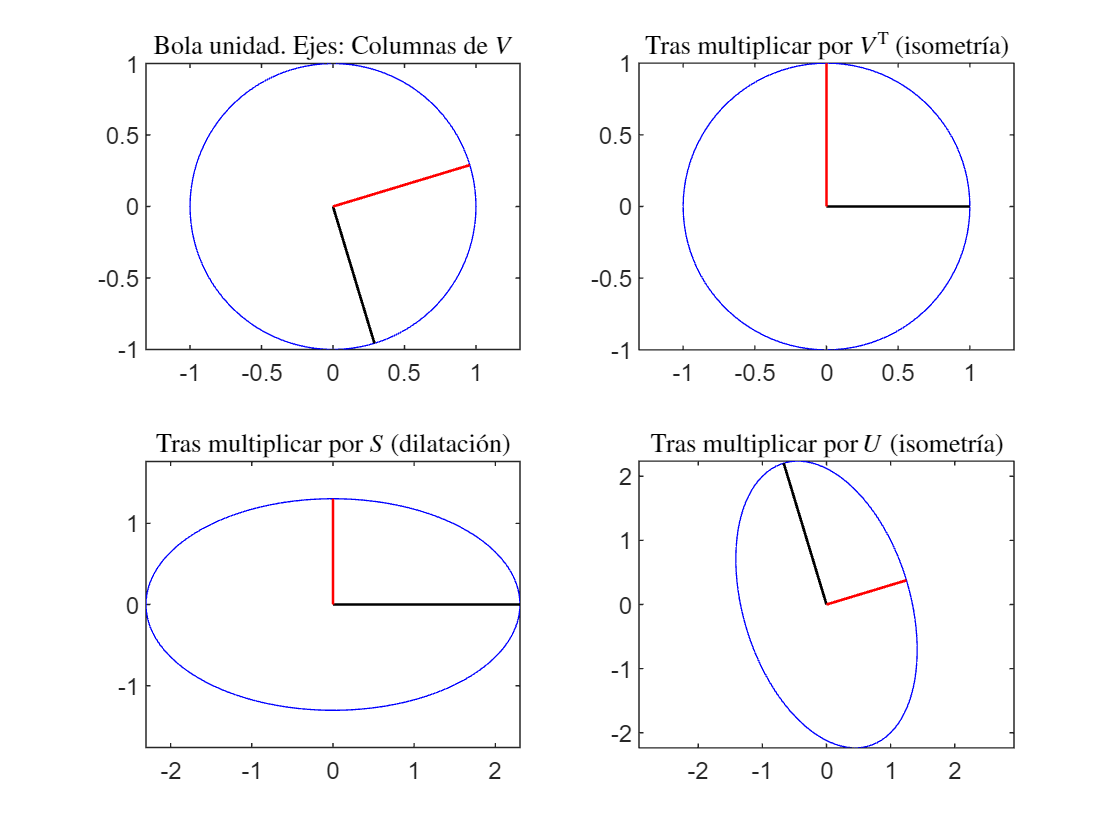

SV=S*V';
US=U*S;
SVp=SV*p;
Ap=A*p;

subplot(2,2,1)
%figure
plot(x,y,'b')
hold on
plot([V(1,1) 0],[V(2,1) 0],'LineWidth',1,'Color','black');
plot([V(1,2) 0],[V(2,2) 0],'LineWidth',1,'Color','red');
title("Bola unidad. Ejes: Columnas de $V$",'interpreter','latex')
axis equal
hold off

subplot(2,2,2)
%figure
plot(x,y,'b')
hold on
plot([1 0],[0 0],'LineWidth',1,'Color','black');
plot([0 0],[1 0],'LineWidth',1,'Color','red');
title("Tras multiplicar por $V^{\rm T}$ (isometr\'{i}a)",'interpreter','latex')
axis equal
hold off

subplot(2,2,3)
%figure
plot(SVp(1,:),SVp(2,:),'b')
hold on
plot([S(1,1) 0],[S(2,1) 0],'LineWidth',1,'Color','black');
plot([S(1,2) 0],[S(2,2) 0],'LineWidth',1,'Color','red');
title("Tras multiplicar por $S$ (dilataci\'{o}n)",'interpreter','latex')
axis equal
hold off

subplot(2,2,4)
%figure
plot(Ap(1,:),Ap(2,:),'b')
hold on
plot([US(1,1) 0],[US(2,1) 0],'LineWidth',1,'Color','black');
plot([US(1,2) 0],[US(2,2) 0],'LineWidth',1,'Color','red');
title("Tras multiplicar por $U$ (isometr\'{i}a)",'interpreter','latex')
axis equal
hold off

De esta forma, los ejes de la elipse en que se transforma la circunferencia unidad son los correspondientes a los vectores

E1=

disp([US(1,1);US(2,1)])

   -0.6673
    2.2040



de longitud 

disp(S(1,1))

    2.3028



 y E2=

disp([US(1,2);US(2,2)])

    1.2469
    0.3775



de longitud

disp(S(2,2))

    1.3028

